clear all;
close all;
clc;

# Global thresholding reactions 

This code is designed to execute the global thresholding algorithm.

It is necessary to use COBRAToolbox, a MATLAB toolbox specifically for metabolic network analysis and model reconstruction. The Gurobi solver is also used, although MATLAB's built-in solver can be used.

## Initialize the COBRA Toolbox and set the solver to Gurobi

The Gurobi solver is initialised, as well as COBRAToolbox.

gurobi_setup;


The MATLAB interface for Gurobi 10.0.1 has been installed.

The directory
    C:\gurobi1001\win64\matlab\
has been added to the MATLAB path.
To use Gurobi regularly, you must save this new path definition.
To do this, type the command
    savepath
at the MATLAB prompt. Please consult the MATLAB documentation
if necessary.


initCobraToolbox(false);



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2024
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.37.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.


 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [*---] GUROBI_PATH: C:\gurobi1001\win64\matlab
   - [----] TOMLAB_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ...     0

     0

Check osense*c - A'*lam - w = 0 (stationarity):
     0
     0


 > [gurobi] Primal optimality condition in solveCobraLP satisfied.
 > [gurobi] Dual optimality condition in solveCobraLP satisfied.


changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested

   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:     Byunggyoo Kim (SOL), Chris Maes (ICME)
                     Santiago Akle (ICME), Matt Zahr (ICME)
                     Aekaansh Verma (ME)                   
   --------------------------------------------------------

The objective is linear

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ...Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested
 Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

					Support           LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    1 	    1 	    1 	    1 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek    

setenv('GUROBI_PATH', 'C:\gurobi1001\win64\matlab');
changeCobraSolver('gurobi', 'all');


 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for LP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for MILP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for QP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only b

## Load data

Gene expression data, the list of housekeeping genes and the metabolic model to be used are uploaded.

CHECK THE DIFFERENCES BETWEEN MODEL AND MODEL_ALICIA

currentFolder = pwd;
cd('C:/Users/PC/OneDrive/Documentos/Systems_Biology_master/Internship/Internship/Data');
data = readtable("data_TPM.xlsx");
h_k_g = readtable('NM2ENSG.xlsx');
%model = load('Human-GEM_Cobra_v1.01.mat')
%model = model.model
model = load('SysBio_COBRA_v1.17_consensus.mat'); % Human1 metabolic model
model = model.myModel;
% model_Alicia = load('SysBio_COBRA_v1.17_consensus1.mat');
% model_Alicia = model_Alicia.myModel;

## Ensure the model does not contain blocked reactions

The Genome-Scale Metabolic model may contain blocked reactions, which could affect further analysis, so it is recommended to remove these. 

WE DON'T DO THIS ANYMORE BECAUSE WE ARE LOSING A LOT OF INFORMATION

USE THE PRUNED MODEL TO CALCULATE THE METABOLIC GENES AND REACTIONS, AND THE NOT PRUNE FOR THE HK AND THE CORE GENES AND REACTIONS

% [fluxConsistentMetBool, fluxConsistentRxnBool, fluxInConsistentMetBool, fluxInConsistentRxnBool, ~, fluxConsistModel] = findFluxConsistentSubset(model);
% model = fluxConsistModel; % load the new model with no blocked reactions
% save('model', 'model');
model_p = load('model.mat');
model_p = model_p.model;
model_genes_p = model_p.genes; % ENSEMBL_IDs of the genes in the model
model_genes = model.genes;
cd(currentFolder)

## Preprocessing

Depending on the dataset, different steps will be required. The points we are interested in obtaining are the ENSEMBL_IDs of the genes, the sample names, and normalising the gene expression data.

To normalise, a log10 of the data is made, to which a 1 is added to avoid that values that are 0 give -inf values.

Finally, a table is created with the new normalised data, the column names are the sample names, and the first column is the ENSEML_IDs.

% Colect the data needed to create the table
Ensembl_id = data(:, 1);
sampleNames = data.Properties.VariableNames(2:end); 
data_to_log = table2array(data(:, 2:end));
%logged_data = log10(data_to_log + 1); % Normalize the data (+1 to avoid having 0 values) 

%Create the new table with the data obtained before
log_data = [Ensembl_id, array2table(data_to_log)]; % Load the data on the new table  
log_data.Properties.VariableNames(2:end) = sampleNames; % Variables names 
log_data.Properties.VariableNames{1} = 'gene'; % Change ENSEML_ID name to gene (To run findUsedGenesLevels)

## Processing the gene expression dataset

Not all genes in the dataset are metabolism-related genes. This part of the code is responsible for obtaining the expression of the metabolic genes (metabolic_genes).

% UNPRUNED MODEL
geneExpressionMatrix = [];

for i = 1: width(sampleNames)
    log_data.value = log_data{:, i + 1}; %- min(log_data{:, i + 1}); % shift minimum to 0 ¡¡ ASK MARIAN HOW HE WANT TO NORMALIZE IT!! ACTUALLY IT SAYS FPKM, SO I ALREADY HAVE IT
    [geneList, geneExpression] = findUsedGenesLevels(model, log_data); % Athough is just for the last sample, the genes present in the models are always the same
    geneExpressionMatrix = [geneExpressionMatrix, geneExpression'];
    log_data.value = [];
end

metabolic_genes = array2table(geneExpressionMatrix, 'RowNames', geneList, 'VariableNames', sampleNames);

% Delete the NaN values
metabolic_genes = rmmissing(metabolic_genes, 'MinNumMissing', size(metabolic_genes, 2)); % So we can use the local thresholding 

% Take the metabolic ENSEMBL_IDs for later
gene_names = metabolic_genes.Properties.RowNames;

% PRUNED MODEL
geneExpressionMatrix_P = [];

for i = 1: width(sampleNames)
    log_data.value = log_data{:, i + 1}; %- min(log_data{:, i + 1}); % shift minimum to 0 ¡¡ ASK MARIAN HOW HE WANT TO NORMALIZE IT!! ACTUALLY IT SAYS FPKM, SO I ALREADY HAVE IT
    [geneList, geneExpression] = findUsedGenesLevels(model_p, log_data); % Athough is just for the last sample, the genes present in the models are always the same
    geneExpressionMatrix_P = [geneExpressionMatrix_P, geneExpression'];
    log_data.value = [];
end

metabolic_genes_P = array2table(geneExpressionMatrix_P, 'RowNames', geneList, 'VariableNames', sampleNames);

% Delete the NaN values
metabolic_genes_P = rmmissing(metabolic_genes_P, 'MinNumMissing', size(metabolic_genes_P, 2)); % So we can use the local thresholding 

% Take the metabolic ENSEMBL_IDs for later
gene_names_P = metabolic_genes_P.Properties.RowNames;

## Global thresholding to determine core and non-core genes

DO A PLOT, FOR 25% OF THE GENES HOW MANY CORE REACTIONS OUT OF ALL THE REACTIONS

This part of the code goes through the samples, setting a threshold based on the 75th percentile. All genes with an expression above that threshold are considered core-gene. These core-genes (their ENSEMBL_ID) is stored inside the resutls_CoreGenes structure.

results_CoreGenes = table;
numSamples = length(sampleNames);
Percentile75 = zeros(1, numSamples);
Gene_exp_norm = zeros(length(gene_names_P), numSamples);

for i = 1:numSamples
    col_name = sampleNames{i};
    expData = metabolic_genes(:, col_name);
    expData.Properties.VariableNames{1} = 'ExpressionValue';
    Percentile75_value = prctile(expData.ExpressionValue, 75);

    expData_P = metabolic_genes_P(:, col_name);
    expData_P.Properties.VariableNames{1} = 'ExpressionValue';
    expData_P.Value = expData_P.ExpressionValue; %- min(expData.LogExpressionValue);
    %Percentile75_value = prctile(expData.Value, 75);
    expData_P.Value = expData_P.Value/Percentile75_value;
    Gene_exp_norm(:, i) = expData_P.Value;
    coreGenesIdx = expData_P.Value >= 1; % Percentile 75
    coreGenes = expData_P(coreGenesIdx, :);
    coreGeneIDs = coreGenes.Properties.RowNames;
    results_CoreGenes{i, 'Sample'} = {col_name};
    results_CoreGenes{i, 'CoreGeneIDs'} = {coreGeneIDs};
    Percentile75(i) = Percentile75_value;
end


disp(results_CoreGenes);

         Sample         CoreGeneIDs 
    ________________    ____________

    {'BJ_Y1'       }    {585×1 cell}
    {'BJ_Y2'       }    {585×1 cell}
    {'BJ_Y3'       }    {585×1 cell}
    {'BJ_OLD_1'    }    {591×1 cell}
    {'BJ_OLD_2'    }    {593×1 cell}
    {'BJ_OLD_3'    }    {592×1 cell}
    {'IMR90_Y1'    }    {583×1 cell}
    {'IMR90_Y2'    }    {587×1 cell}
    {'IMR90_Y3'    }    {583×1 cell}
    {'IMR90_O1'    }    {581×1 cell}
    {'IMR90_O2'    }    {592×1 cell}
    {'IMR90_O3'    }    {594×1 cell}
    {'WI_38_Y1'    }    {582×1 cell}
    {'WI_38_Y2'    }    {583×1 cell}
    {'WI_38_Y3'    }    {582×1 cell}
    {'WI_38_O1'    }    {588×1 cell}
    {'WI_38_O2'    }    {588×1 cell}
    {'WI_38_O3'    }    {594×1 cell}
    {'HFF_PD16_1'  }    {582×1 cell}
    {'HFF_PD16_2'  }    {581×1 cell}
    {'HFF_PD16_3'  }    {583×1 cell}
    {'HFF_PD74_1'  }    {588×1 cell}
    {'HFF_PD74_2'  }    {583×1 cell}
    {'

## Map genes to reactions for each sample and determine the core reactions

We also want to measure the accuracy of the core-reactions. This part of the code, based on the genes, obtains its expression and based on it the reactions are obtained using the mapExpressionToReactions function. Using the value of the percentile 75 we stabilsh the core-reactions in CoreReact_Sample.

% %Initialize variables
% 
% Rxns_global = [];
% geneUsed_global = cell(1, numSamples);
% parsedGPR_global = cell(1, numSamples);
% CoreReact_Sample = cell(1, numSamples);
% 
% for i = 1:numSamples
%     col_name = sampleNames{i};
%     expData_P = array2table(Gene_exp_norm(:, i), 'VariableNames', {'ExpressionValue'});
%     expData_P.gene = gene_names_P;
% 
%     % Structure for map expression
%     expressionDataSample.gene = expData_P.gene;
%     expressionDataSample.value = expData_P.ExpressionValue;
% 
%     % Map expression to reactions
%     [expressionRxns, parsedGPR, gene_used] = mapExpressionToReactions(model_p, expressionDataSample, 'false');
%     Rxns_global = [Rxns_global; expressionRxns];
%     geneUsed_global{i} = gene_used;
%     parsedGPR_global{i} = parsedGPR;
% 
%     % Active reactions
%     CoreReact_Sample{i} = model_p.rxns(expressionRxns >= 1);
% end
% 
% % Save the results
% save('Rxns_global.mat', 'Rxns_global');
% save('geneUsed_global.mat', 'geneUsed_global');
% save('parsedGPR_global.mat', 'parsedGPR_global');
% save('CoreReact_Sample.mat', 'CoreReact_Sample');

% Load them
Rxns_global = load('Rxns_global.mat');
Rxns_global = Rxns_global.Rxns_global;
geneUsed_global = load('geneUsed_global.mat');
geneUsed_global = geneUsed_global.geneUsed_global;
parsedGPR_global = load('parsedGPR_global.mat');
parsedGPR_global = parsedGPR_global.parsedGPR_global;
CoreReact_Sample = load('CoreReact_Sample.mat');
CoreReact_Sample = CoreReact_Sample.CoreReact_Sample;


## Housekeeping gene analysis

Now it starts the analysis for Housekeeping gene list. As it happens with the dataset, not all the housekeeping genes are related with the metabolism. We choose those ones that are related to the metabolism.

hkg_met = model_p.genes(ismember(model_p.genes, h_k_g.converted_alias));%hkg_met = metabolic_genes(index_names, :);

% To reactions
results_HKReact = findRxnsFromGenes_Alicia(model_p, hkg_met);

Input: string of single gene or cell array of multiple genes



% Extract unique housekeeping reaction names
fields = fieldnames(results_HKReact);
housekeep_react = {};
for i = 1:length(fields)
    field = fields{i};
    cellArray = results_HKReact.(field);
    for j = 1:size(cellArray, 1)
        firstcol = cellArray{j, 1};
        housekeep_react{end+1, 1} = firstcol;
    end
end
housekeep_react_unique = unique(housekeep_react);
disp(housekeep_react_unique);

    {'MAR00001'}
    {'MAR00003'}
    {'MAR00005'}
    {'MAR00006'}
    {'MAR00010'}
    {'MAR00067'}
    {'MAR00080'}
    {'MAR00091'}
    {'MAR00113'}
    {'MAR00114'}
    {'MAR00115'}
    {'MAR00117'}
    {'MAR00118'}
    {'MAR00121'}
    {'MAR00122'}
    {'MAR00129'}
    {'MAR00133'}
    {'MAR00153'}
    {'MAR00154'}
    {'MAR00155'}
    {'MAR00158'}
    {'MAR00164'}
    {'MAR00167'}
    {'MAR00170'}
    {'MAR00173'}
    {'MAR00176'}
    {'MAR00179'}
    {'MAR00183'}
    {'MAR00187'}
    {'MAR00188'}
    {'MAR00190'}
    {'MAR00191'}
    {'MAR00192'}
    {'MAR00195'}
    {'MAR00196'}
    {'MAR00199'}
    {'MAR00200'}
    {'MAR00203'}
    {'MAR00204'}
    {'MAR00208'}
    {'MAR00209'}
    {'MAR00212'}
    {'MAR00213'}
    {'MAR00216'}
    {'MAR00217'}
    {'MAR00225'}
    {'MAR00226'}
    {'MAR00232'}
    {'MAR00233'}
    {'MAR00236'}
    {'MAR00237'}
    {'MAR00240'}
    {'MAR00241'}
    {'MAR00244'}
    {'MAR00245'}
    {'MAR00248'}
    {'MAR00249'}
    {'MAR00254'}
    {'MAR00255

## Compare the number of housekeeping core genes

This part of the code gives the percentage of metabolic core-housekeeping genes out of the total amount of metabolic housekeeping genes 

housekep_core_gene_G = struct("numHousekeepingCoreGenes", [], 'housekeepingCoreGenes', [], 'percentage', []);
totalHousekeepingGenes = numel(hkg_met);

for i = 1:numSamples
    coreGenes = results_CoreGenes.CoreGeneIDs{i};
    housekeepingGeneNames = hkg_met;
    housekeepingInCore_g = ismember(housekeepingGeneNames, coreGenes);
    housekep_core_gene_G(i).numHousekeepingCoreGenes = sum(housekeepingInCore_g);
    housekep_core_gene_G(i).housekeepingCoreGenes = housekeepingGeneNames(housekeepingInCore_g);
    housekep_core_gene_G(i).percentage = (housekep_core_gene_G(i).numHousekeepingCoreGenes / totalHousekeepingGenes) * 100;
end

HK_G_acc_G = [housekep_core_gene_G.percentage];
HK_G_acc_G_col = HK_G_acc_G(:)

HK_G_acc_G_col =    50.8108
   50.8108
   50.8108
   50.9910
   51.1712
   51.1712
   52.4324
   52.2523
   52.0721
   52.0721


T_Genes = table(HK_G_acc_G_col, 'VariableNames', {'HK_G_acc_G'});
writetable(T_Genes, "HK_G_acc_G.xlsx", 'WriteRowNames', false);

## Compare the number of housekeeping core reactions

This part of the code gives the percentage of metabolic core-housekeeping reactions out of the total amount of metabolic housekeeping reactions. 

housekep_core_react_G = struct('numHousekeepingCoreReactions', [], 'housekeepingCoreReactions', [], 'percentage', []);
totalHousekeepingReactions = numel(housekeep_react_unique);

for i = 1:numSamples
    coreReactions = CoreReact_Sample{i};
    housekeepingInCore = ismember(housekeep_react_unique, coreReactions);
    housekep_core_react_G(i).numHousekeepingCoreReactions = sum(housekeepingInCore);
    housekep_core_react_G(i).housekeepingCoreReactions = housekeep_react_unique(housekeepingInCore);
    housekep_core_react_G(i).percentage = (housekep_core_react_G(i).numHousekeepingCoreReactions / totalHousekeepingReactions) * 100;
end

HK_R_acc_G = [housekep_core_react_G.percentage];
HK_R_acc_G_col = HK_R_acc_G(:)

HK_R_acc_G_col =    71.1609
   70.7495
   68.6472
   68.8757
   69.1042
   70.2925
   68.2358
   69.6527
   68.3729
   68.3729


T_React = table(HK_R_acc_G_col, 'VariableNames', {'HK_R_acc_G'});
writetable(T_React, "HK_R_acc_G.xlsx", 'WriteRowNames', false);


# Plot

SOLVE THIS: WITH THE PERCENTAGE METABOLIC GENES THAT ARE IN THE CORE GENE. THRESHOLD FOR UNPRUNED MODEL, AND CORE-GENES AND REACTIONS IN THE PRUNED ONE.

DO THE PLOT WITH THRESHOLDS AND HOUSEKEEPING RECALL FOR GENES. AND FOR REACTIONS

- plot, on the xs the core gene set, and on the y the housekeeping core reactions recal

% % Pruned and unpruned data
% IMR90_Y2 = table2array(metabolic_genes(:, 8))
% IMR90_Y2_P = table2array(metabolic_genes_P(:, 8))
% 
% % Core genes and core reactions
% %IMR90_Y2_coreGenes = results_CoreGenes(8, 'CoreGeneIDs');
% %test = IMR90_Y2_coreGenes{1, 1};
% IMR90_Y2_length = length(IMR90_Y2_P);
% 
% % for core Reactions
% %IMR90_Y2_coreReact = CoreReact_Sample(1, 8)
% IMR90_Y2_RLength = length(model_p.rxns);%IMR90_Y2_coreReact{1, 1})
% 
% % Initialises vectors for storing recall values
% HK_CG_G = zeros(1, 100);
% HK_CR_R = zeros(1, 100);
% HK_CG_G_recall_values = zeros(1, 100);
% HK_CR_R_recall_values = zeros(1, 100);
% 
% % Loop to iterate over each percentile
% for p = 1:100
%     percentile_value = prctile(IMR90_Y2, p);
% 
%     % Normalises data based on the current percentile
%     IMR90_Y2_norm = IMR90_Y2_P ./ percentile_value;
% 
%     % Calculate the recall for core genes
%     IMR90_Y2_CG = gene_names_P(IMR90_Y2_norm >= 1);
%     HK_CG_G(p) = (length(IMR90_Y2_CG)/IMR90_Y2_length)*100;
%     HK_CG_G_rec = hkg_met(ismember(hkg_met, IMR90_Y2_CG));
%     HK_CG_G_recall = (length(HK_CG_G_rec) / length(hkg_met)) * 100;
%     HK_CG_G_recall_values(p) = HK_CG_G_recall;
% 
%     % Prepare the expression data
%     expressionData.gene = gene_names_P;
%     expressionData.value = IMR90_Y2_norm;
% 
%     % Map gene expression to reactions
%     IMR90_Y2_normCR = mapExpressionToReactions(model_p, expressionData, 'false'); % Maybe here with the pruned one?
%     IMR90_Y2_CR = model_p.rxns(IMR90_Y2_normCR >= 1);
% 
%     % Calculate the recall for core reactions
%     HK_CR_R(p) = (length(IMR90_Y2_CR)/IMR90_Y2_RLength)*100;
%     HK_CR_R_rec = housekeep_react_unique(ismember(housekeep_react_unique, IMR90_Y2_CR));
%     HK_CR_R_recall = (length(HK_CR_R_rec) / length(housekeep_react_unique)) * 100;
%     HK_CR_R_recall_values(p) = HK_CR_R_recall;
% end

## Save the results and load them

% save('HK_CG_G.mat', 'HK_CG_G');
% save('HK_CG_G_recall_values.mat', 'HK_CG_G_recall_values');
% save('IMR90_Y2_norm.mat', 'IMR90_Y2_norm');
% save('IMR90_Y2_normCR.mat', 'IMR90_Y2_normCR');
% save('HK_CR_R.mat', 'HK_CR_R');
% save('HK_CR_R_recall_values.mat', 'HK_CR_R_recall_values');

% Load the data
HK_CG_G = load('HK_CG_G.mat');
HK_CG_G = HK_CG_G.HK_CG_G;
HK_CG_G_recall_values = load('HK_CG_G_recall_values.mat');
HK_CG_G_recall_values = HK_CG_G_recall_values.HK_CG_G_recall_values;
IMR90_Y2_norm = load('IMR90_Y2_norm.mat');
IMR90_Y2_norm = IMR90_Y2_norm.IMR90_Y2_norm;
IMR90_Y2_normCR = load('IMR90_Y2_normCR.mat');
IMR90_Y2_normCR = IMR90_Y2_normCR.IMR90_Y2_normCR;
HK_CR_R = load('HK_CR_R.mat');
HK_CR_R = HK_CR_R.HK_CR_R;
HK_CR_R_recall_values = load('HK_CR_R_recall_values.mat');
HK_CR_R_recall_values = HK_CR_R_recall_values.HK_CR_R_recall_values;

## Plot the results

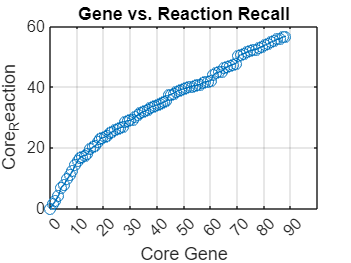

% CORE GENE INCLUSSION VS CORE REACTION INCLUSION
plot(HK_CG_G, HK_CR_R, 'o-');
xlabel('Core Gene');
ylabel('Core_Reaction');
title('Gene vs. Reaction Recall');
grid on;
xticks(0:10:90);
% Save the plot
saveas(gcf, 'Gene_vs_Reaction.png');

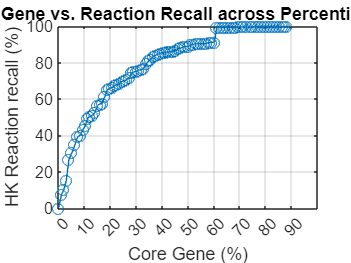


% CORE GENE INCLUSION VS HOUSEKEEPING REACTIONS RECALL
plot(HK_CG_G, HK_CR_R_recall_values, 'o-');
xlabel('Core Gene (%)');
ylabel('HK Reaction recall (%)');
title('Gene vs. Reaction Recall across Percentiles');
grid on;
xticks(0:10:90);
% Save the plot
saveas(gcf, 'Gene_vs_HKReaction.png');

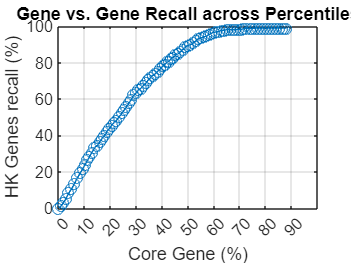


% CORE GENE INCLUSION VS HOUSEKEEPING GENES RECALL
plot(HK_CG_G, HK_CG_G_recall_values, 'o-');
xlabel('Core Gene (%)');
ylabel('HK Genes recall (%)');
title('Gene vs. Gene Recall across Percentiles');
grid on;
xticks(0:10:90);
% Save the plot
saveas(gcf, 'Gene_vs_HKGene.png');

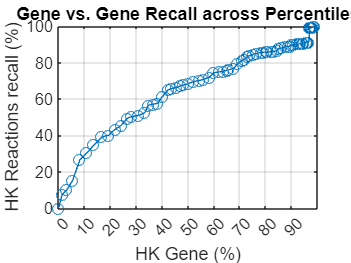


% HOUSEKEEPING GENE RECALL VS HOUSEKEEPING REACTIONS RECALL
plot(HK_CG_G_recall_values, HK_CR_R_recall_values, 'o-');
xlabel('HK Gene (%)');
ylabel('HK Reactions recall (%)');
title('Gene vs. Gene Recall across Percentiles');
grid on;
xticks(0:10:max(HK_CG_G_recall_values));

% Save the plot
saveas(gcf, 'HKGene_vs_HKReactions.png');

# TEST WHAT MARIAN SUGGESTED ABOUT PERCENTAGE OF ORs

% % Pruned and unpruned data
% IMR90_Y2 = table2array(metabolic_genes(:, 8))
% IMR90_Y2_P = table2array(metabolic_genes_P(:, 8))
% 
% % Core genes and core reactions
% %IMR90_Y2_coreGenes = results_CoreGenes(8, 'CoreGeneIDs');
% %test = IMR90_Y2_coreGenes{1, 1};
% IMR90_Y2_length = length(IMR90_Y2_P);
% 
% % for core Reactions
% %IMR90_Y2_coreReact = CoreReact_Sample(1, 8)
% IMR90_Y2_RLength = length(model_p.rxns);%IMR90_Y2_coreReact{1, 1})
% 
% % Initialises vectors for storing recall values
% HK_CG_G_T = zeros(1, 40);
% HK_CR_R_T = zeros(1, 40);
% HK_CG_G_recall_values_T = zeros(1, 40);
% HK_CR_R_recall_values_T = zeros(1, 40);
% HK_CG_G_T_Names = {};
% HK_CR_R_T_Names = {};
% 
% % Loop to iterate over each percentile
% for p = 100:-1:60
%     percentile_value = prctile(IMR90_Y2, p);
% 
%     % Normalises data based on the current percentile
%     IMR90_Y2_norm = IMR90_Y2_P ./ percentile_value;
% 
%     % Calculate the recall for core genes
%     IMR90_Y2_CG = gene_names_P(IMR90_Y2_norm >= 1);
%     HK_CG_G_T_Names{p} = IMR90_Y2_CG;
%     HK_CG_G_T(p) = (length(IMR90_Y2_CG)/IMR90_Y2_length)*100;
%     HK_CG_G_rec_T = hkg_met(ismember(hkg_met, IMR90_Y2_CG));
%     HK_CG_G_recall_T = (length(HK_CG_G_rec_T) / length(hkg_met)) * 100;
%     HK_CG_G_recall_values_T(p) = HK_CG_G_recall_T;
% 
%     % Prepare the expression data
%     expressionData.gene = gene_names_P;
%     expressionData.value = IMR90_Y2_norm;
% 
%     % Map gene expression to reactions
%     IMR90_Y2_normCR = mapExpressionToReactions(model_p, expressionData, 'false'); % Maybe here with the pruned one?
%     IMR90_Y2_CR = model_p.rxns(IMR90_Y2_normCR >= 1);
% 
%     % Calculate the recall for core reactions
%     HK_CR_R_T_Names{p} = IMR90_Y2_CR;
%     HK_CR_R_T(p) = (length(IMR90_Y2_CR)/IMR90_Y2_RLength)*100;
%     HK_CR_R_rec = housekeep_react_unique(ismember(housekeep_react_unique, IMR90_Y2_CR));
%     HK_CR_R_recall = (length(HK_CR_R_rec) / length(housekeep_react_unique)) * 100;
%     HK_CR_R_recall_values_T(p) = HK_CR_R_recall;
% end
% 
% save('HK_CG_G_T_Names.mat', 'HK_CG_G_T_Names');
% save('HK_CR_R_T_Names.mat', 'HK_CR_R_T_Names');

% load the data
HK_CG_G_T_Names = load('HK_CG_G_T_Names.mat');
HK_CG_G_T_Names = HK_CG_G_T_Names.HK_CG_G_T_Names;
HK_CR_R_T_Names = load('HK_CR_R_T_Names.mat');
HK_CR_R_T_Names = HK_CR_R_T_Names.HK_CR_R_T_Names;


## Check the or and AND rules

Go throught the 60 percentile one by one, to explore the reactions that are included, and based on that, analyze the percentage of those that are coded by 'or' rules.

% Save the GPR rules
GPR_rules = model_p.grRules;

% Initialize tables for 'and' & 'or' words in GPR rules
count_and = zeros(1, length(HK_CR_R_T_Names));
count_or = zeros(1, length(HK_CR_R_T_Names));
total_reactions_count = zeros(1, length(HK_CR_R_T_Names));  % To store the total number of reactions for each set

% Loop to iterate over each set of core reactions
for i = length(HK_CR_R_T_Names):-1:1
    current_reactions = HK_CR_R_T_Names{i};
    total_reactions = length(current_reactions);
    total_reactions_count(i) = total_reactions;  % Save the total number of reactions in this set
    count_and_i = 0;
    count_or_i = 0;
    if total_reactions == 0
        continue;  % Skip this iteration if there are no reactions
    end
    % Loop over each reaction in the current set
    for j = 1:total_reactions
        reaction_name = current_reactions{j};
        % Find the index of this reaction in model_p.rxns
        index = find(strcmp(model_p.rxns, reaction_name));
        if isempty(index)  % Check if the index is empty
            continue;  % Skip this iteration if no reaction found
        end
        % Access the corresponding GPR rule
        gpr_rule = GPR_rules{index};
        % Check and count occurrences of 'and' and 'or'.
        if contains(gpr_rule, 'and')
            count_and_i = count_and_i + 1;
        end
        if contains(gpr_rule, 'or')
            count_or_i = count_or_i + 1;
        end
    end
    % Store counts for this iteration
    count_and(i) = count_and_i;
    count_or(i) = count_or_i;
end

% Calculate the percentage of occurrences for 'and' and 'or'.
percent_and = (count_and ./ total_reactions_count) * 100;
percent_or = (count_or ./ total_reactions_count) * 100;

% Show results
disp(['Porcentaje de "and": ', num2str(percent_and)]);

Porcentaje de "and": NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN      6.607143      6.340206      6.461781      5.736393      5.676621      5.757162       4.46304      4.409271      4.557406      4.315913      4.371097      4.39

disp(['Porcentaje de "or": ', num2str(percent_or)]);

Porcentaje de "or": NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN      66.58163       67.1134      68.16391      69.02348      69.38391       70.0955      71.46444      71.50933      72.91849      72.90076      73.29765      73.35

## TEST

[onlyOR, anyAND, singleGene] = analyzeGPRWithExpression(model_p, data)

onlyOR = 3574

anyAND = 725

singleGene = 2926

# ADITIONAL CHECK, NOT IMPORTANT

## Check the samples with the same accuracy with genes

Some of the samples have the same accuracy. This part of the code check if the metabolic core-housekeeping genes of those samples are the same or not.

% find the indexes of the same values
 equalIndex = {};

 for i = height(HK_G_acc_G_col)
     index = find(HK_G_acc_G_col == HK_G_acc_G_col(i));
     if length(index) > 1 && ~any(cellfun(@(x) isequal(x, index), equalIndex))
         equalIndex{end+1} = index
     end
 end

equalIndex = 1×1 cell array
    {5×1 double}



% Check the HK core genes names 
genesArray = housekep_core_gene_G.housekeepingCoreGenes;

for i = 1:length(equalIndex)
    indexGrup = equalIndex{i};
    genesGrup = genesArray{indexGrup(1)};
    areEqual = true;
    for j = 2:length(indexGrup)
        genesCompare = genesArray{indexGrup(j)};
        if length(genesGrup) ~= length(genesCompare) || ~all(strcmp(genesGrup, genesCompare))
            areEqual = false;
            break;
        end
    end
    resultsCompare{i} = areEqual;
end

## Check the samples with the same accuracy with reactions

Some of the samples have the same accuracy. This part of the code check if the metabolic core-housekeeping reactions of those samples are the same or not.

% find the indexes of the same values
 equalIndex = {};

 for i = height(HK_R_acc_G_col)
     index = find(HK_R_acc_G_col == HK_R_acc_G_col(i));
     if length(index) > 1 && ~any(cellfun(@(x) isequal(x, index), equalIndex))
         equalIndex{end+1} = index
     end
 end

equalIndex = 1×1 cell array
    {2×1 double}



% Check the HK core genes names 
genesArray = housekep_core_react_G.housekeepingCoreReactions;

for i = 1:length(equalIndex)
    indexGrup = equalIndex{i};
    reactGrup = genesArray{indexGrup(1)};
    areEqual = true;
    for j = 2:length(indexGrup)
        reactCompare = genesArray{indexGrup(j)};

        if length(reactGrup) ~= length(genesCompare) || ~all(strcmp(reactGrup, reactCompare))
            areEqual = false;
            break;
        end
    end
    resultsCompare_R{i} = areEqual;
end
